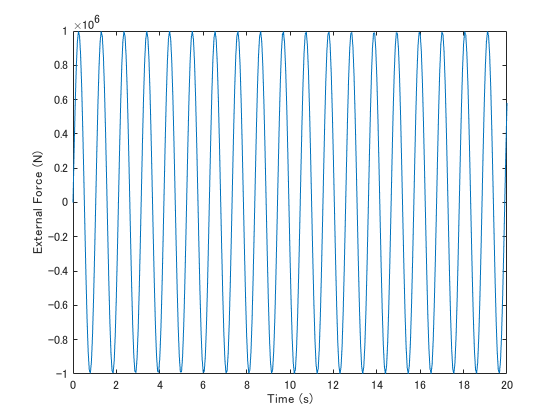

% ここ構造モデル

% 質量m [kg]
m = 2*10^6;

% 減衰定数c
c = 0.02;

% ばね定数k [N/m]
k = 5*10^6 / (10/200);

% 固有周期系角速度（rad/s）
w = (k/m)^0.5;

% 固有周期T [s]
T = 2*pi/w;



% ここ外力 p0 * sin(wp*t)

% 外力の振幅 [N]
p0 = 1*10^6;

% 外力の角速度 [rad/s]
wp = 6;

% 外力の周期 [s]
Tp = 2*pi/wp;



% ここ応答計算

% 固有振動形角速度比 β
beta = wp/w;

% 振幅G
G = (p0/k)/(1-beta^2);

% 時刻 t
t = 0:0.05:20;

% 外力プロット p
p = p0*sin(wp*t);

plot(t,p)
xlabel('Time (s)')
ylabel('External Force (N)')

print -dpng ./04/figure1